# GRAPPA MRI Reconstruction

## Initializing

tic
close;
clear;

## Loading data

brainCoilsData = load('brain_coil.mat');
brainCoils = brainCoilsData.brain_coil_tmp;
[phaseLength, freqLength, numCoils] = size(brainCoils);
disp(size(brainCoils));  % Phases, Frequencies, Coils

   120   128     5



## Show original Brain Image

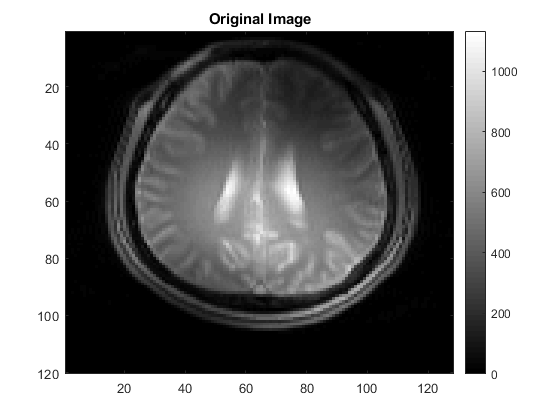

originalImage = rsos(brainCoils);
imagesc(originalImage);

title('Original Image');
colormap('gray');
colorbar();

## Convert to Fourier Domain with 2D Fast Fourier Transform

Don't forget to use fftshift and ifftshift.

fullKspace = fftshift(fftshift(fft2(brainCoils), 1), 2);

## Check k-space

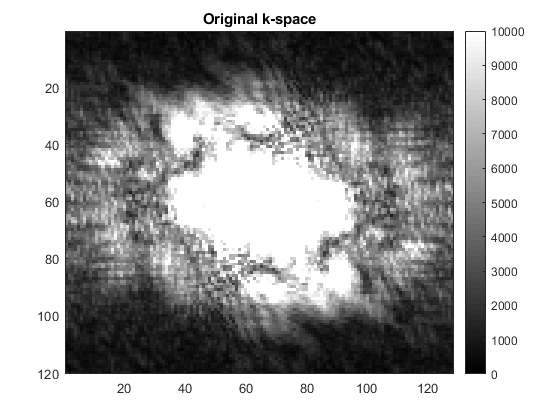

imagesc(rsos(fullKspace), [0, 10000]);
title('Original k-space');
colormap('gray');
colorbar();

## Setting parameters for later use.

Due to overlap with the downsampling lines, the actual ACS length may be 1 or 2 lines longer than specified.

samplingRate = 2;
acsLength = 12;
kernelHeight = 4;
kernelWidth = 3;
remainder = 0;

assert(mod(kernelHeight, 2) == 0, 'kernel height should be an even number')
assert(mod(kernelWidth, 2) == 1, 'kernel width should be an odd number')
assert(remainder < samplingRate, ...
    'The remainder must be a non-negative integer smaller than the sampling rate.')

## Making the mask

Creating a mask for the downsampling and the acs lines.

mask = zeros(size(fullKspace));  % Making a mask for the brain coils.

acsStart = floor((phaseLength - acsLength) ./ 2);
acsFinish = acsStart + acsLength;

for idx=1:phaseLength
    if (acsStart < idx) && (idx <= acsFinish)
        mask(idx, :, :) = 1;
    end
    
    if mod(idx, samplingRate) == remainder
        mask(idx, :, :) = 1;
    end
end

assert(isequal(size(mask), size(brainCoils)), 'Mask size is incorrect.')

## Displaying mask.

This code functions to check whether the mask has been made correctly.

All values should be either 0 or 1. The presence of any other value indicates an error.

There should be a white band in the middle, with striped lines surrounding it.

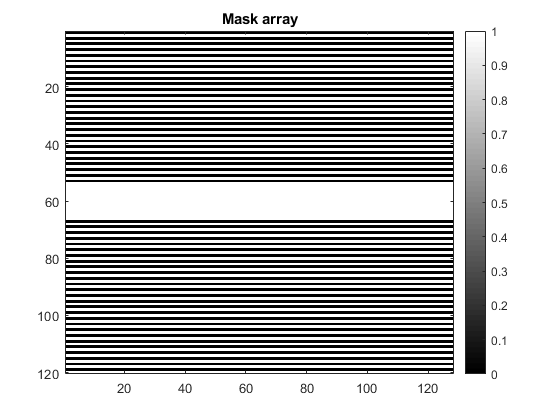

imagesc(mean(mask, 3));
title('Mask array');
colormap('gray');
colorbar();

## Generating down-sampled k-space

Obtain the Hadamard product (elementwise matrix multiplication) between the full k-space data and the mask.

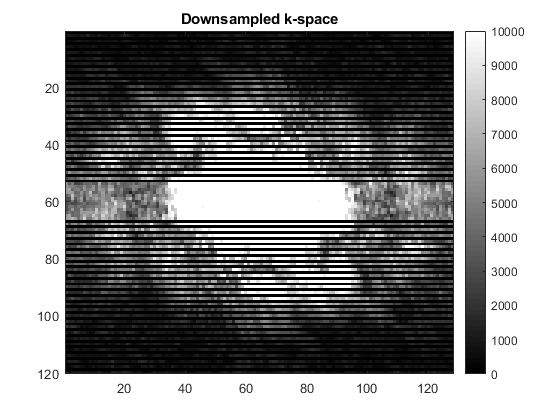

downSampledKspace = fullKspace .* mask;
assert(isequal(size(downSampledKspace), size(brainCoils)), 'Reconstruction is of the wrong shape.')

imagesc(rsos(downSampledKspace), [0, 10000]);
title('Downsampled k-space');
colormap('gray');
colorbar();

## Check Downsampled Image

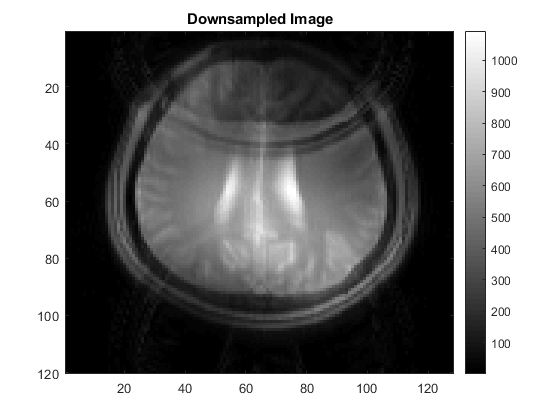

dsImage = ifft2(ifftshift(ifftshift(downSampledKspace, 2), 1));
dsImage = rsos(dsImage);

imagesc(dsImage);
title('Downsampled Image');
colormap('gray');
colorbar();

## Find True ACS

Find the length of the true ACS domain, including lines due to downsampling.

finder = any(downSampledKspace, [2, 3]);
assert(isequal(finder, mean(mask, [2, 3])), 'The indices are wrong.')

acsFinder = zeros(phaseLength, 1);
for idx=2:phaseLength-1
    if finder(idx-1) == 1 && finder(idx) == 1 && finder(idx+1) == 1
        acsFinder(idx-1:idx+1) = 1;
    end
end

% Getting the idices of the ACS lines.
acsLines = find(acsFinder);

% Checking whether the parameters fit.
matrixHeight = samplingRate .* (kernelHeight-1) + 1;
acsTrueLength = length(acsLines);

assert(acsTrueLength >= matrixHeight, 'ACS is too short for kernel params')
assert((acsLength <= acsTrueLength) && (acsTrueLength <= acsLength+2), 'Mask is incorrect')

## Building the weight matrix

Has equation of X * w = Y in mind.

X = inMatrix, Y = outMatrix, w = weights.

Each kernel adds one row to the X and Y matrices.

acsPhases = acsTrueLength - matrixHeight + 1;
numKernels = acsPhases .* freqLength;
kernelSize = kernelHeight .* kernelWidth .* numCoils;
outSize = numCoils .* (samplingRate - 1);

inMatrix = zeros(numKernels, kernelSize);
outMatrix = zeros(numKernels, outSize);
hkw = floor(kernelWidth/2);  % Half kernel width.
hkh = kernelHeight/2;  % Half kernel height.
kidx = 1;  % "Kernel index" for counting the number of kernels.
for acsLine=acsLines(1:acsPhases)'
    phases = linspace(acsLine, acsLine+matrixHeight-1, kernelHeight);  % Phases of the kernel
    for freq=1:freqLength
        freqs = linspace(freq-hkw, freq+hkw, kernelWidth);  % Frequencies of the kernel.
        freqs = mod(freqs-1, freqLength) + 1;  % For circular indexing.
        
        selected = linspace(phases(hkh)+1, phases(hkh+1)-1, samplingRate-1);
        selected = mod(selected-1, phaseLength) + 1;  % Selected Y phases.
        
        tempX = downSampledKspace(phases, freqs, :);
        tempY = downSampledKspace(selected, freq, :);
        
        % Filling in the matrices row by row.
        inMatrix(kidx, :) = reshape(tempX, 1, kernelSize);
        outMatrix(kidx, :) = reshape(tempY, 1, outSize);
        
        kidx = kidx + 1;
    end
end

assert(isequal(size(inMatrix), [numKernels, kernelSize]), 'Incorrect X matrix');
assert(isequal(size(outMatrix), [numKernels, outSize]), 'Incorrect Y matrix');

weights = pinv(inMatrix) * outMatrix;  % Calculate the weight matrix.
assert(isequal(size(weights), [kernelSize, outSize]), 'Incorrect weight size');

## GRAPPA Reconstruction

Performing a naive reconstruction according to first principles causes an overlap problem.

The lines immediately before and after the ACS lines are not necessarily spaced with the sampling rate as the spacing.

This causes alteration of the original data if GRAPPA reconstruction is performed naively.

The solution is to perform reconstruction on a blank, and then overwrite all vlaues with the original data.

This alleviates the problem of having to do special operations for the values at the edges.

Also, the lines of k-space at the start or end of k-space may be neglected (depending on the implementation).

This requires shifting the finder by the sampling rate to look at the phase from one step above.

If the downsampling does not match due to incorrect k-space dimensions, errors will be overwritten by the final correction process.

% Find the indices to fill, including at the beginning of k-space.
temp1 = find(diff(finder) == -1) + 1;  % Gets nearly all the lines.
temp2 = find(diff(circshift(finder, samplingRate)) == -1) - samplingRate + 1;
% Second line exists to catch the first few empty lines,
% if any are present.
fillFinder = unique([temp1; temp2]);

% Shift from first fill line to beginning of kernel data.
upShift = (hkh-1) .* samplingRate + 1;
% Shift from first fill line to end of kernel data.
downShift = hkh .* samplingRate - 1;

grappaKspace = zeros(size(downSampledKspace));

for phase=fillFinder'
    phases = linspace(phase-upShift, phase+downShift, kernelHeight);
    phases = mod(phases-1, phaseLength) + 1;  % Circularly indexed phases.
    for freq=1:freqLength
        freqs = linspace(freq-hkw, freq+hkw, kernelWidth);
        freqs = mod(freqs-1, freqLength) + 1;  % Circularly indexed frequencies.
        
        kernel = downSampledKspace(phases, freqs, :);
        % One line of the input matrix.
        tempX = reshape(kernel, 1, kernelSize);
        
        % One line of the output matrix.
        tempY = tempX * weights;
        tempY = reshape(tempY, (samplingRate-1), 1, numCoils);
        
        % Selected lines of the output matrix to be filled in.
        selected = linspace(phases(hkh)+1, phases(hkh+1)-1, samplingRate-1);
        selected = mod(selected-1, phaseLength) + 1;
        
        grappaKspace(selected, freq, :) = tempY;
    end
end

% Filling in all the original data.
% Doing it this way solves the edge overlap problem.
grappaKspace(finder, :, :) = downSampledKspace(finder, :, :);

assert(isequal(size(downSampledKspace), size(grappaKspace)), 'Incorrect matrix size.');
% Somewhat redundant assertion now.
% assert(isequal(grappaKspace(finder, :, :), downSampledKspace(finder, :, :)));

## Display recon image

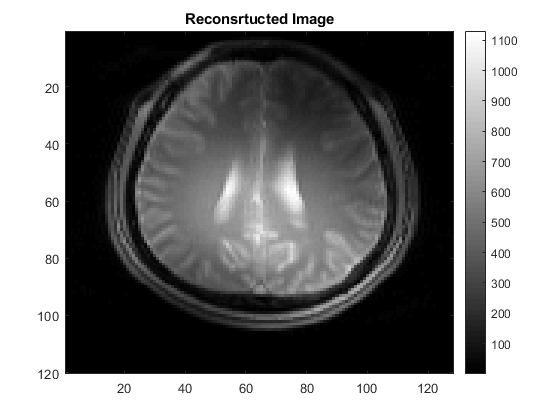

recon = ifft2(ifftshift(ifftshift(grappaKspace, 2), 1));
temp = recon(:, :, 1);
reconImage = rsos(recon);

imagesc(reconImage);
title('Reconsrtucted Image');
colormap('gray');
colorbar();

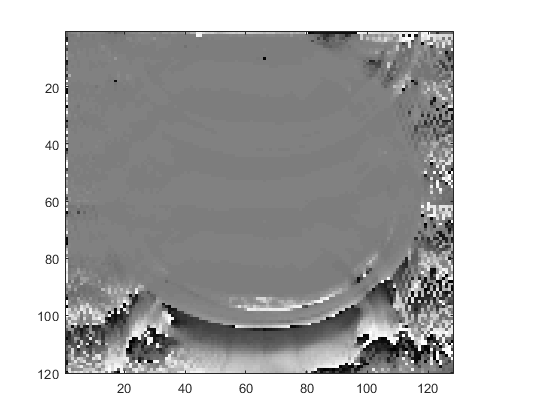

imagesc(angle(temp));

## Display difference image

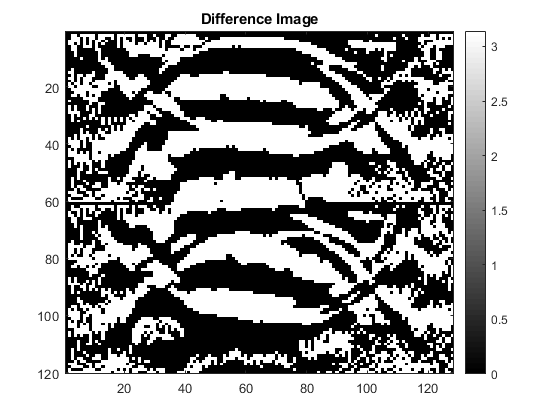

deltaImage = reconImage - originalImage;

imagesc(angle(deltaImage));
title('Difference Image');
colormap('gray');
colorbar();

## Summary

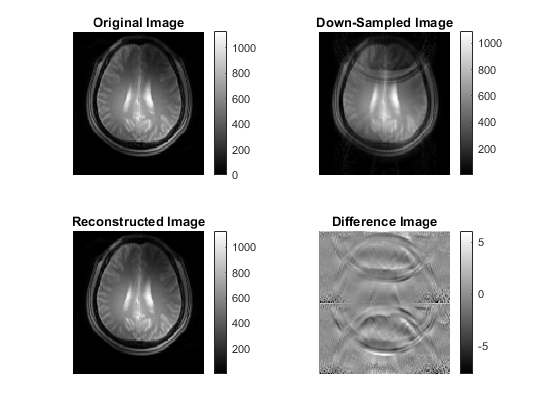

subplot(2, 2, 1);
imagesc(originalImage);
title('Original Image');
colormap('gray');
axis('off');
colorbar();

subplot(2, 2, 2);
imagesc(dsImage);
title('Down-Sampled Image');
colormap('gray');
axis('off');
colorbar();

subplot(2, 2, 3);
imagesc(reconImage);
title('Reconstructed Image');
colormap('gray');
axis('off');
colorbar();

subplot(2, 2, 4);
imagesc(deltaImage);
title('Difference Image');
colormap('gray');
axis('off');
colorbar();


toc

Elapsed time is 2.413136 seconds.
